% Example 7.7
% 수동 PID 제어
% K가 무려 3개!!

% KD, KI = 0
% KP 구하는 과정
clear all
sys = tf([1],[1 15.66 56.6 0])

sys =
 
             1
  ------------------------
  s^3 + 15.66 s^2 + 56.6 s
 
연속시간 전달 함수입니다.
모델 속성


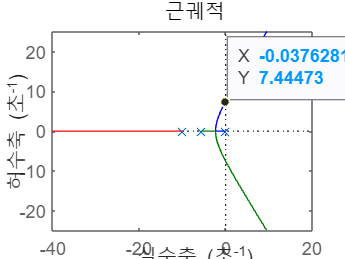

figure();
rlocus(sys);

% 2번째 overshoot이 1번째의 1/4배쯤인 KP = 370 로 하자!

% KP = 370, KI = 0
% KD 구하는 과정
clear all
sys = tf([1 0],[1 15.66 56.6 370])

sys =
 
                s
  ------------------------------
  s^3 + 15.66 s^2 + 56.6 s + 370
 
연속시간 전달 함수입니다.
모델 속성


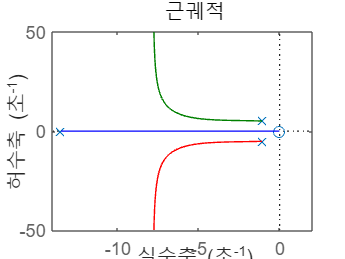

figure();
rlocus(sys);

% KD가 증가하면서 pole이 같은 실수부를 갖는게 가장 stable 하겠네!!

% KP = 370, KD = 0 (KD와 KI는 서로 간섭하니 KI를 구할 때도 KD = 0 으로 하고 구하자)
% KI 구하는 과정
clear all
sys = tf([1],[1 15.66 56.6 370 0])

sys =
 
                  1
  ----------------------------------
  s^4 + 15.66 s^3 + 56.6 s^2 + 370 s
 
연속시간 전달 함수입니다.
모델 속성


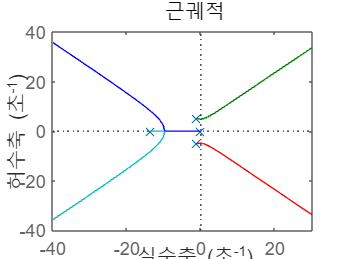

figure();
rlocus(sys);

% KI가 778.2보다 크면 unstable(실수부가 양수인게 생김) 해지므로 그보다 작은 값에서 찾자.

% KP = 370, KD = 60, KI = 100 일 때 백분율 overshoot와 정착시간
clear all
syms Ls s G

KP = 370;
KD = 60;
KI = 100;
Ls = (KD*s^2 + KP*s + KI)/(s^4 + 15.66*s^3 + 56.6*s^2)

$$Ls = \frac{60\,s^{2}+370\,s+100}{s^{4}+\frac{783\,s^{3}}{50}+\frac{283\,s^{2}}{5}}$$

G = simplify(Ls/(1 + Ls))

$$G = \frac{3000\,s^{2}+18500\,s+5000}{50\,s^{4}+783\,s^{3}+5830\,s^{2}+18500\,s+5000}$$

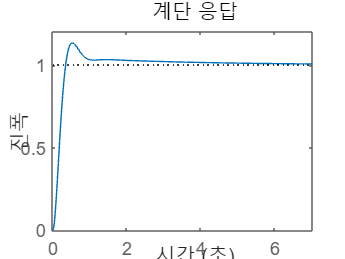

[n, d] = numden(G);
num = sym2poly(n);
den = sym2poly(d);

sys = tf(num, den);
step(sys);

Per_Overshoot = (max(step(sys))-1)*100 % 백분율 오버슈트

Per_Overshoot = 13.4062


% 다른 방법
[n, d] = numden(Ls);
num = sym2poly(n);
den = sym2poly(d);
sys_1 = tf(num, den)

sys_1 =
 
   3000 s^2 + 18500 s + 5000
  ---------------------------
  50 s^4 + 783 s^3 + 2830 s^2
 
연속시간 전달 함수입니다.
모델 속성


sys = feedback(sys_1,1)

sys =
 
           3000 s^2 + 18500 s + 5000
  --------------------------------------------
  50 s^4 + 783 s^3 + 5830 s^2 + 18500 s + 5000
 
연속시간 전달 함수입니다.
모델 속성


step(sys);